# First Slice HDF5 -> bin -> MTEX

**Use code as base for future datasets, its separated in sections to be run more smoothly and with a more easily understandeable structure**

#### Max Solis 02/07/2024

# Z slices (100-102)

#### Sectioning

% Inputs
nRow = 1531;
nCol = 1301;
height = 1531;  
width = 1301;  
start_row = 1;  
start_col = 1;  

Vtemp = (1:(nRow*nCol)).';
Mtemp = reshape(Vtemp,nRow, nCol);
IDX = Mtemp(start_row:start_row+height-1, start_col:start_col+width-1);
IDXsec = IDX(:)

IDXsec =      1
     2
     3
     4
     5
     6
     7
     8
     9
    10


### IDs and pores

poreID = fopen('PhaseID_pore_100.bin');
A = fread(poreID);
pores_2M = ismember(A, 0);
find(pores_2M);

### Grain IDs

flabels = fopen('labels_100.bin');
D = fread(flabels,'int')

D =        12114
       12114
       12114
       12114
       12114
       12114
       12114
       12114
       12114
       12114


labeltemp = reshape(D, [], 1301);
labels = ismember(D, 0);
find(labels);

### Rotations

% feuler = fopen('eulers_100.bin');
% ROtemp = fread(feuler,inf,'float','l');
% ROT = reshape(ROtemp, 3, []).';
% rot = rotation.byEuler(ROT);

feuler = fopen('quat_100.bin');
ROtemp = fread(feuler,inf,'float','l');
ROT = reshape(ROtemp, 4, []);
quat = quaternion(ROT);
rot = rotation(quat);

### Properties

fbse = fopen('BSE_100.bin');
bsetemp = fread(fbse,inf,'float','l');
fci = fopen('CI_100.bin');
citemp = fread(fci,inf,'float','l');
ffit = fopen('Fit_100.bin');
fittemp = fread(ffit,inf,'float','l');
fiq = fopen('IQ_100.bin');
iqtemp = fread(fiq,inf,'float','l');

prop.ci = citemp(IDXsec);
prop.grainid = D(IDXsec);
prop.iq = iqtemp(IDXsec);
prop.bse = bsetemp(IDXsec);
xlin = 0:0.75:1147.5;
xtemp = repmat(xlin,1,1301).';
ylin = 0:0.75:975;
ytemp = repelem(ylin, 1531).';
prop.x = xtemp(IDXsec);
prop.y = ytemp(IDXsec);
prop.mad = fittemp(IDXsec);
CSList = {'Pore', 'Austenite'};

### EBSD

ebsdsec = EBSD(rot(IDXsec),A(IDXsec),CSList,prop)

 
ebsdsec = EBSD
 
 Phase    Orientations    Mineral  Color  Symmetry
     0    2953 (0.15%)       Pore                 
     1  1988878 (100%)  Austenite                 
 
 Properties: ci, grainid, iq, bse, x, y, mad
 Scan unit : um
 


% ebsdsec.orientations = orientation.byEuler(ROT(IDXsec, 1:3));
ebsdsec.orientations = orientation.byEuler(rot.phi1(IDXsec),rot.Phi(IDXsec),rot.phi2(IDXsec));
ori = ebsdsec.orientations;
odf = calcDensity(ori);

### Plots

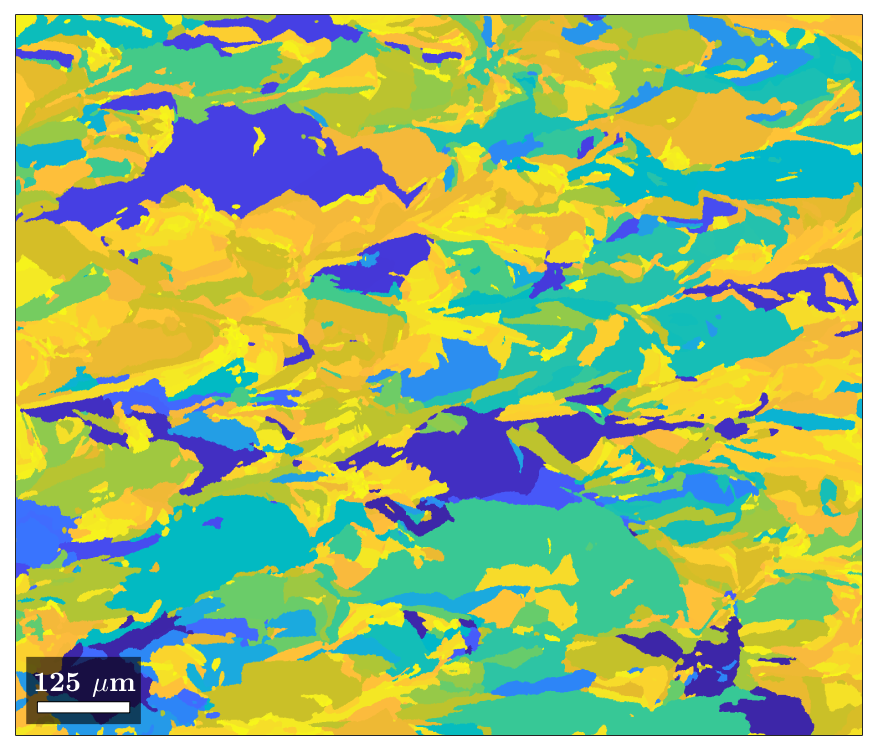

figure()
plot(ebsdsec, ebsdsec.grainid)

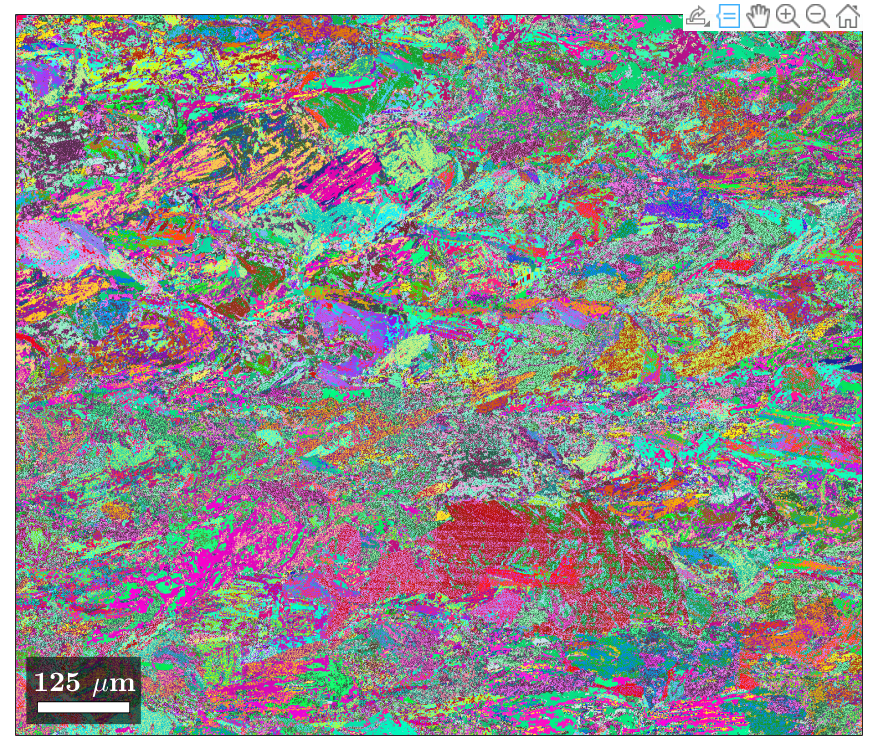

  I'm going to colorize the orientation data with the 
  standard MTEX ipf colorkey. To view the colorkey do:
 
  ipfKey = ipfColorKey(ori_variable_name)
  plot(ipfKey)



figure()
plot(ebsdsec, ebsdsec.orientations)


% [grains,ebsdsec.grainId] = calcGrains(ebsdsec('indexed'),'threshold',10*degree);
% ebsdsec(grains(grains.grainSize < 10)) = [];
% [grains,ebsdsec.grainId] = calcGrains(ebsdsec('indexed'),'threshold',10*degree);
% grains = smooth(grains,5);
% colors = ipfKey.orientation2color(grains.meanOrientation);
% figure()
% plot(grains, colors)

% figure()
% ipfKey = ipfHSVKey(ebsdsec.CS.properGroup);
% plot(ipfKey)
% color = ipfKey.orientation2color(ebsdsec.orientations);
% figure()
% plot(ebsdsec,color)

% figure()
% ori = ebsdsec.orientations;
% odf = calcDensity(ori)
% plot(odf)

% figure()
% [grains,ebsdsec.grainid] = calcGrains(ebsdsec);
% grains(grains.grainSize < 10) = [];
% plot(grains.boundary,'color','k','linewidth',1.5)
% 
% [grains,ebsdsec.grainId] = calcGrains(ebsdsec,'angle',5*degree);
% ipfKey = ipfHSVKey(ebsdsec);
% colors = ipfKey.orientation2color(ebsdsec.orientations);
% ipfKey.colorPostRotation = reflection(yvector);
% % plot the ebsd data together with the colors
% figure()
% plot(ebsdsec,colors)
% 
% % plot(grains.boundary,'lineWidth',1.5,'micronbar','off')

id = ebsdsec.prop.grainid

id =        12114
       12114
       12114
       12114
       12114
       12114
       12114
       12114
       12114
       12114


[a,b]=hist(id,unique(id));
sizes = [b,a.']

sizes =           70       14508
          74       21429
         107        5528
         117        4671
         144        1556
         164         616
         523       43443
         541       16078
         624          71
         691        5187


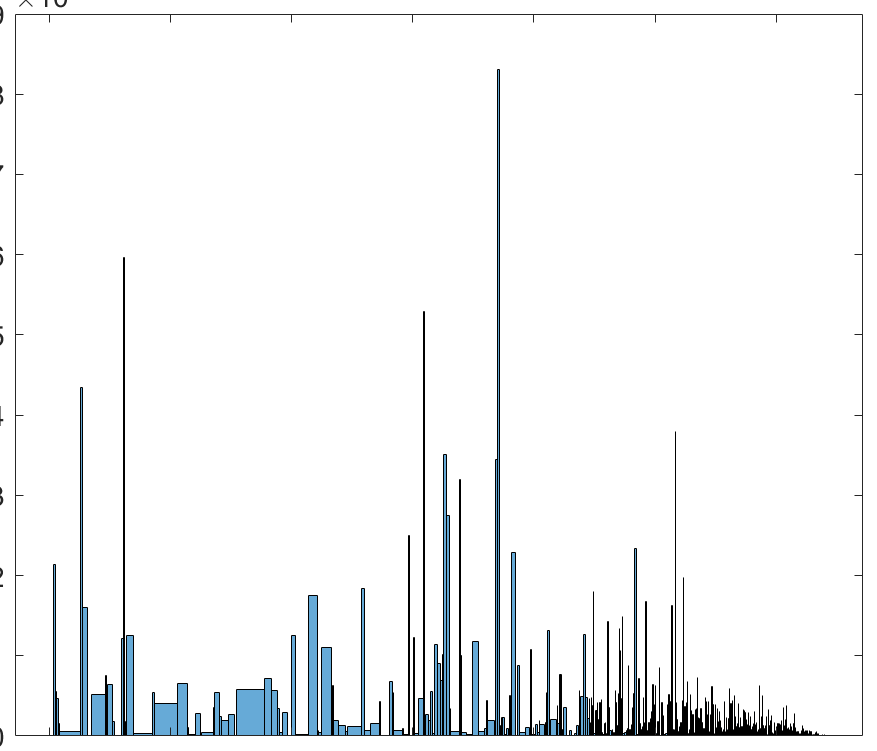

figure()
histogram(id,unique(id))

[B,I] = maxk(sizes,20);
sizIDX = [I(:,2),B(:,2)]

sizIDX =          112       83127
          19       59668
          78       52914
           7       43443
         367       37904
          91       35110
         110       34438
          96       31922
          92       27468
          71       24945
